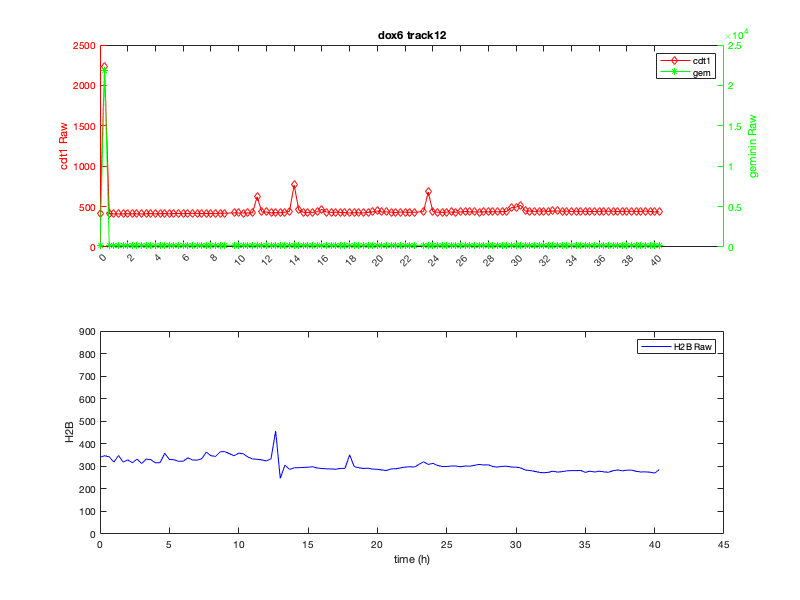

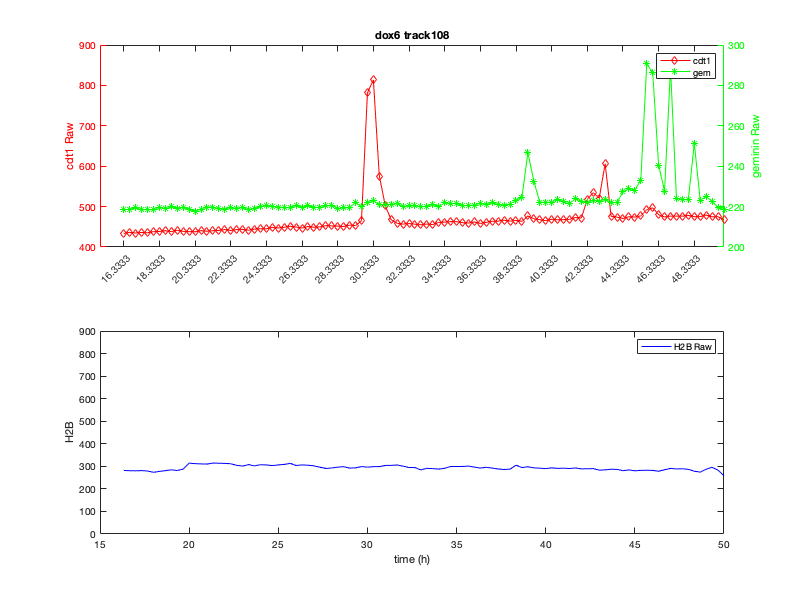

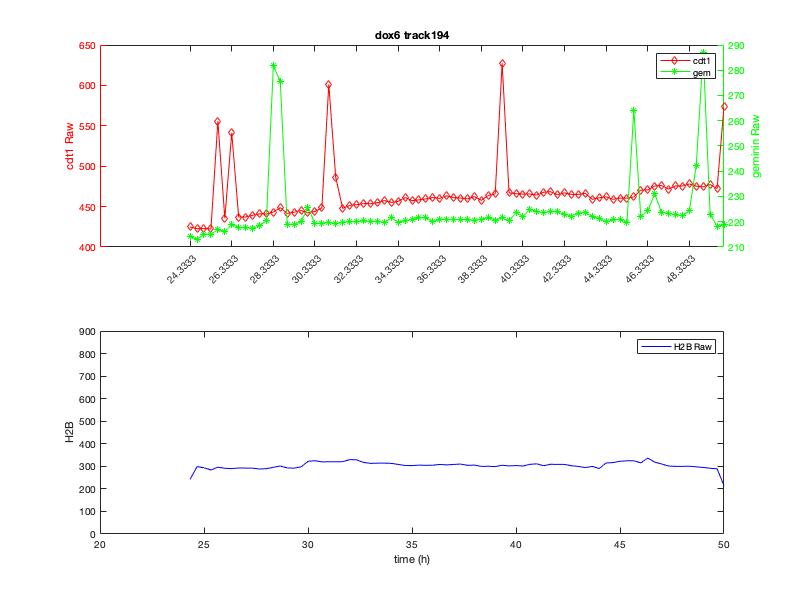

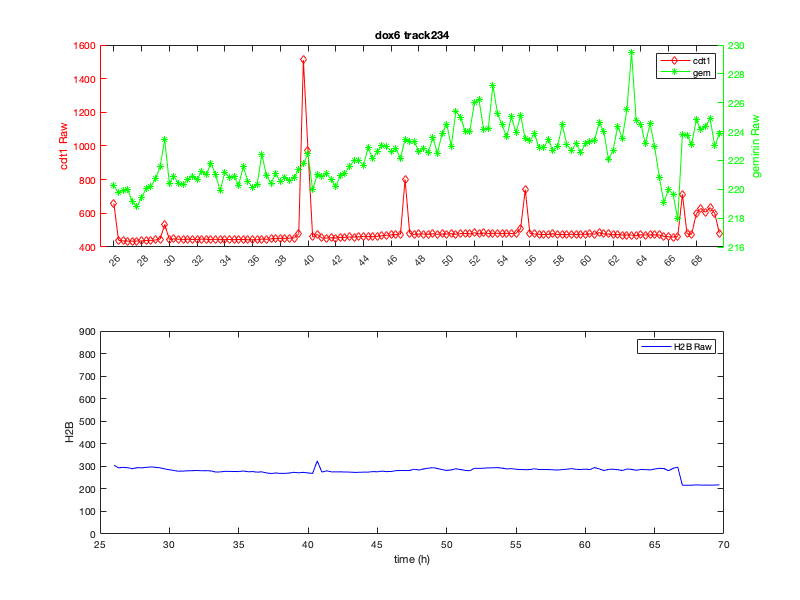

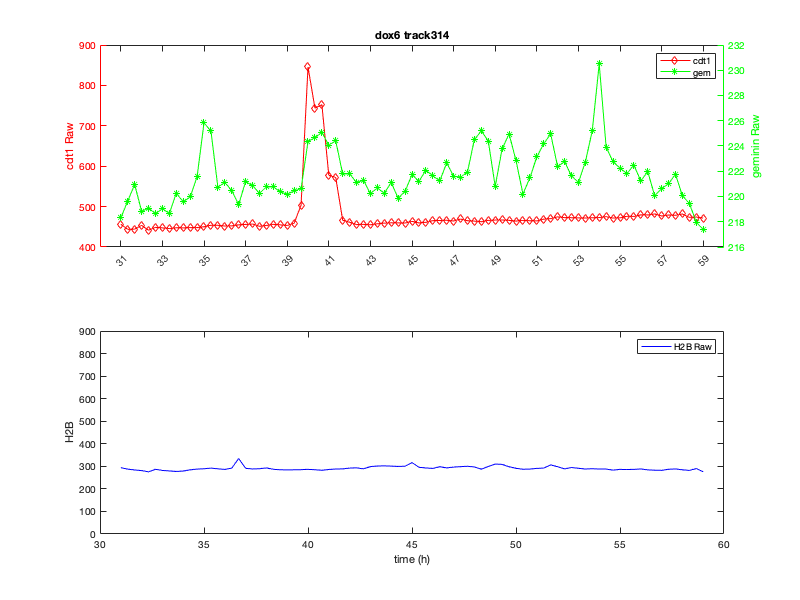

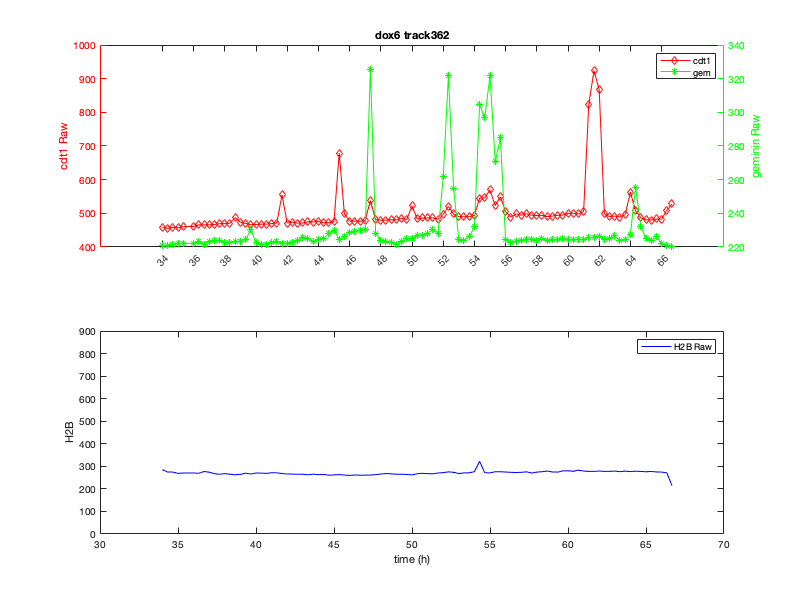

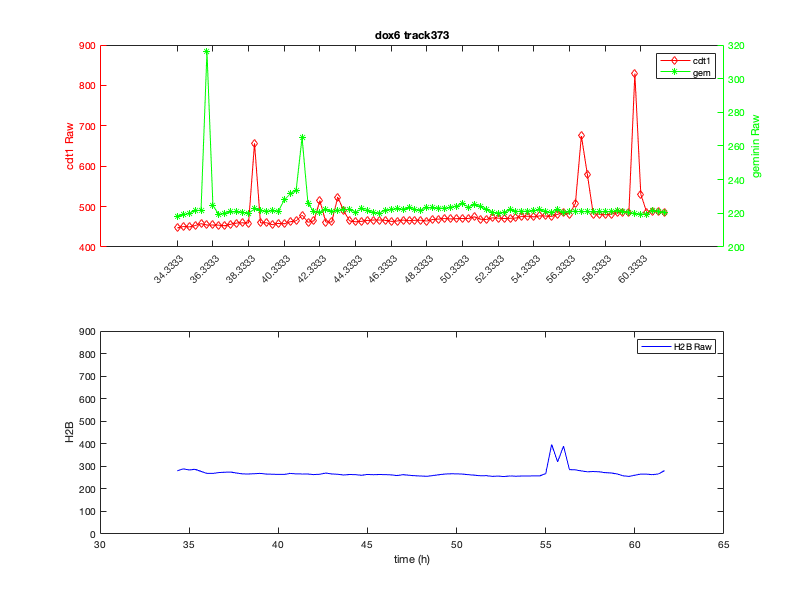

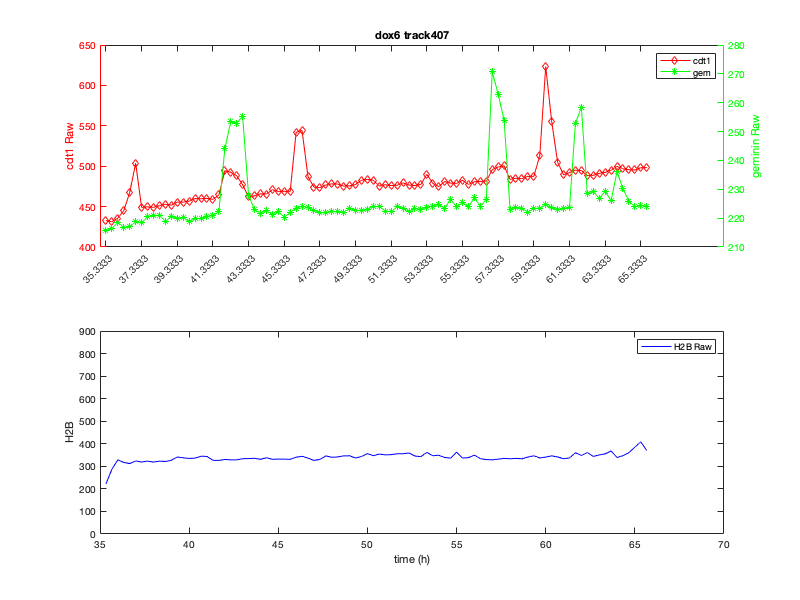

Index in position 1 exceeds array bounds.

%%
clc;
clear all
close all
alldata=readmatrix('Results_dox2.csv');
size = size(alldata);
track_id= alldata(:,3);
time_point = alldata(:,4);
geminin_Mean_RAW = alldata(:,5);
cdt_Mean_RAW = alldata(:,7);
h2b_Mean_RAW= alldata(:,9);
[unique_track_id, locs, apprearance] = unique(track_id);
Locs=locs;
endnumber=length(track_id);
Locs (length(Locs)+1) = endnumber(1,:);


for m = 1:length(locs)
    time = time_point(locs(m):Locs(m+1)-1);
    time = (time-1)/3;
    figure (m)
    tiledlayout(2,1)
    nexttile
    yyaxis right
    geminin = geminin_Mean_RAW(locs(m):Locs(m+1)-1);
    cdt = cdt_Mean_RAW(locs(m):Locs(m+1)-1);
    plot(time, geminin,'*-g')
    ylabel('geminin Raw')
    set(gca,'ycolor','g')
    yyaxis left
    plot(time,cdt,'d-r')
    legend('cdt1','gem')
    ylabel('cdt1 Raw')
    set(gca,'ycolor','r')
    title(['dox2 track',sprintf('%d',unique_track_id(m))]);
    xticks(time(1,:):2:time(end,:))
    xtickangle(45);
    
    nexttile
    h2b=h2b_Mean_RAW(locs(m):Locs(m+1)-1);
    plot(time,h2b,'b');
    ylabel('H2B')
    xlabel('time (h)');
    legend('H2B Raw');
    ylim([0 900])
    
    figname=['track',num2str(m),'.tiff'];
    set(gcf,'position',[10,10,800,600])
    saveas(gcf,figname)
    close(figure(m))
end